## Neural Network

How can a computer take a decision? Let's imagine:


$$z=x_1 *w_1 +x_2 *w_2 +b$$


- $x_1$ and $x_2$: How much do I want to do the activity?

- $w_1$ and $w_2$: What benefits am I getting when doing these activities?

- $b$: What is my mood right now?

You can add as many variables as you want. Suppose you girlfriend got pregnant, what are you going to do? 

- $x_1$ Do I want to have a baby? Not really "0.1"

- $w_1$: Benefits of having a baby  "-0.3"

- $x_2$: Do I love this girl? Yes "0.9"

- $w_2$: Benefits of love a girl? A lot of oxytocin "0.5"

- $b$: What is my mood right now? "0.5"


$$z=0\ldotp 1*-0\ldotp 3+0\ldotp 9*0\ldotp 5+0\ldotp 5$$



$$z=0\ldotp 92$$


We can use the step function to decide rapidly /ˈræpɪdli/ what my decision is or just to use the sigmoid function to give a porcentage of how willing i am.


$$u\left(z\right)=\left\lbrace \begin{array}{ll}
0\;\left(\mathrm{to}\;\mathrm{move}\;\mathrm{abroad}\right) & ,\mathrm{if}\;z<0\\
1\;\left(\mathrm{to}\;\mathrm{take}\;\mathrm{care}\;\mathrm{of}\;\mathrm{the}\;\mathrm{child}\right) & ,\mathrm{if}\;z\ge 0
\end{array}\;\right.$$



$$\sigma \left(z\right)=\frac{1}{1+e^{-z} };\mathrm{How}\;\mathrm{willing}\;i\;\mathrm{am}\;\mathrm{to}\;\mathrm{take}\;\mathrm{care}\;\mathrm{of}\;\mathrm{the}\;\mathrm{child}$$


%{
close all
f = figure('WindowStyle','normal');
set(f,'Units','normalized','Position',[0 0 0.3 0.3]);

plot(z, step, 'LineWidth', 2);
hold on;
plot(z, sigmoid, 'LineWidth', 2);
hold off;

ylim([-0.2 1.2]);
xlabel('z');
ylabel('Salida');
legend('Step function', 'Sigmoid function');
title('Step vs Sigmoid Activation Functions');
grid on;
%}

## 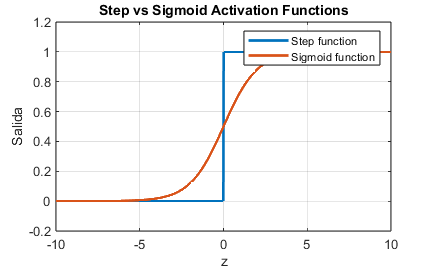

## Sigmoid Function in C

Let's implement the sigmoid function in C: